# 5 Wavelengths PPG Hemoglobin Calculations

The normal range for hemoglobin is:

- For man: 13.5 to 17.5 grams per deciliter (g/dL)——————8.7 to 11.2 Molly/L (SI units)

- For women: 12.0 to 15.5 grams per deciliter

### DATA load

## Set up the Import Options and import the data

opts = delimitedTextImportOptions("NumVariables", 2);

% Specify range and delimiter
opts.DataLines = [1, Inf];
opts.Delimiter = "\t";

% Specify column names and types
opts.VariableNames = ["Time", "V"];
opts.VariableTypes = ["double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
%Mac /Volumes/GoogleDrive/My Drive/Investigacion/Research/Research Project NSF EPSCoR CAWT/Deep Learning/PPG-19-Aug-21
% 
PPG_625_array = table2array(readtable("/Volumes/GoogleDrive/My Drive/Investigacion/Research/Research Project NSF EPSCoR CAWT/Deep Learning/PPG-19-Aug-21/625larry.lvm", opts));
PPG_660_array = table2array(readtable("/Volumes/GoogleDrive/My Drive/Investigacion/Research/Research Project NSF EPSCoR CAWT/Deep Learning/PPG-19-Aug-21/660larry.lvm", opts));
PPG_750_array = table2array(readtable("/Volumes/GoogleDrive/My Drive/Investigacion/Research/Research Project NSF EPSCoR CAWT/Deep Learning/PPG-19-Aug-21/750larry.lvm", opts));
PPG_800_array = table2array(readtable("/Volumes/GoogleDrive/My Drive/Investigacion/Research/Research Project NSF EPSCoR CAWT/Deep Learning/PPG-19-Aug-21/800larry.lvm", opts));
PPG_940_array = table2array(readtable("/Volumes/GoogleDrive/My Drive/Investigacion/Research/Research Project NSF EPSCoR CAWT/Deep Learning/PPG-19-Aug-21/940larry.lvm", opts));


% % Windows New data Larry-Subject_1
% PPG_625_array = table2array(readtable("G:\My Drive\Investigacion\Research\Research Project NSF EPSCoR CAWT\Deep Learning\PPG-19-Aug-21\625larry.lvm", opts));
% PPG_660_array = table2array(readtable("G:\My Drive\Investigacion\Research\Research Project NSF EPSCoR CAWT\Deep Learning\PPG-19-Aug-21\660larry.lvm", opts));
% PPG_750_array = table2array(readtable("G:\My Drive\Investigacion\Research\Research Project NSF EPSCoR CAWT\Deep Learning\PPG-19-Aug-21\750larry.lvm", opts));
% PPG_800_array = table2array(readtable("G:\My Drive\Investigacion\Research\Research Project NSF EPSCoR CAWT\Deep Learning\PPG-19-Aug-21\800larry.lvm", opts));
% PPG_940_array = table2array(readtable("G:\My Drive\Investigacion\Research\Research Project NSF EPSCoR CAWT\Deep Learning\PPG-19-Aug-21\940larry.lvm", opts));

% Windows New Data Maria-Subject_2
% PPG_625_array = table2array(readtable("C:\Users\larry.theran.IRESS\Documents\Labview\New Data test\PPG-07-Sep-21\maria625.lvm", opts));
% PPG_660_array = table2array(readtable("C:\Users\larry.theran.IRESS\Documents\Labview\New Data test\PPG-07-Sep-21\maria660.lvm", opts));
% PPG_750_array = table2array(readtable("C:\Users\larry.theran.IRESS\Documents\Labview\New Data test\PPG-07-Sep-21\maria750.lvm", opts));
% PPG_800_array = table2array(readtable("C:\Users\larry.theran.IRESS\Documents\Labview\New Data test\PPG-07-Sep-21\maria800.lvm", opts));
% PPG_940_array = table2array(readtable("C:\Users\larry.theran.IRESS\Documents\Labview\New Data test\PPG-07-Sep-21\maria940.lvm", opts));
% %

% % Windows New Data Michael-Subject_3
% PPG_625_array = table2array(readtable("C:\Users\larry.theran.IRESS\Documents\Labview\New Data test\PPG-07-Sep-21\michael625.lvm", opts));
% PPG_660_array = table2array(readtable("C:\Users\larry.theran.IRESS\Documents\Labview\New Data test\PPG-07-Sep-21\michael660.lvm", opts));
% PPG_750_array = table2array(readtable("C:\Users\larry.theran.IRESS\Documents\Labview\New Data test\PPG-07-Sep-21\michael750.lvm", opts));
% PPG_800_array = table2array(readtable("C:\Users\larry.theran.IRESS\Documents\Labview\New Data test\PPG-07-Sep-21\michael800.lvm", opts));
% PPG_940_array = table2array(readtable("C:\Users\larry.theran.IRESS\Documents\Labview\New Data test\PPG-07-Sep-21\michael950.lvm", opts));


% % Windows New Data Chhaya-Subject_4
% PPG_625_array = table2array(readtable("C:\Users\larry.theran.IRESS\Documents\Labview\New Data test\PPG-07-Sep-21\chhaya625.lvm", opts));
% PPG_660_array = table2array(readtable("C:\Users\larry.theran.IRESS\Documents\Labview\New Data test\PPG-07-Sep-21\chhaya660.lvm", opts));
% PPG_750_array = table2array(readtable("C:\Users\larry.theran.IRESS\Documents\Labview\New Data test\PPG-07-Sep-21\chhaya750.lvm", opts));
% PPG_800_array = table2array(readtable("C:\Users\larry.theran.IRESS\Documents\Labview\New Data test\PPG-07-Sep-21\chhaya800.lvm", opts));
% PPG_940_array = table2array(readtable("C:\Users\larry.theran.IRESS\Documents\Labview\New Data test\PPG-07-Sep-21\chhaya950.lvm", opts));


% % Windows New Data estefania-Subject_5
% PPG_625_array = table2array(readtable("C:\Users\larry.theran.IRESS\Documents\Labview\New Data test\PPG-07-Sep-21\stefania625.lvm", opts));
% PPG_660_array = table2array(readtable("C:\Users\larry.theran.IRESS\Documents\Labview\New Data test\PPG-07-Sep-21\stefania660.lvm", opts));
% PPG_750_array = table2array(readtable("C:\Users\larry.theran.IRESS\Documents\Labview\New Data test\PPG-07-Sep-21\stefania750.lvm", opts));
% PPG_800_array = table2array(readtable("C:\Users\larry.theran.IRESS\Documents\Labview\New Data test\PPG-07-Sep-21\stefania800.lvm", opts));
% PPG_940_array = table2array(readtable("C:\Users\larry.theran.IRESS\Documents\Labview\New Data test\PPG-07-Sep-21\stefania950.lvm", opts));

% % Windows New Data Heidy-Subject_6
% PPG_625_array = table2array(readtable("C:\Users\larry.theran.IRESS\Documents\Labview\New Data test\PPG-07-Sep-21\heidy625.lvm", opts));
% PPG_660_array = table2array(readtable("C:\Users\larry.theran.IRESS\Documents\Labview\New Data test\PPG-07-Sep-21\heidy660.lvm", opts));
% PPG_750_array = table2array(readtable("C:\Users\larry.theran.IRESS\Documents\Labview\New Data test\PPG-07-Sep-21\heidy750.lvm", opts));
% PPG_800_array = table2array(readtable("C:\Users\larry.theran.IRESS\Documents\Labview\New Data test\PPG-07-Sep-21\heidy800.lvm", opts));
% PPG_940_array = table2array(readtable("C:\Users\larry.theran.IRESS\Documents\Labview\New Data test\PPG-07-Sep-21\heidy940.lvm", opts));


fs=20; %sampling rate 20Hz
PPG_Time = PPG_625_array(1:1246,1); % Selecting 60 seconds of data, to avoid initial data and final data

PPG_625 = PPG_625_array(1:1246,2);
PPG_660 = PPG_660_array(1:1246,2);
PPG_750 = PPG_750_array(1:1246,2);
PPG_800 = PPG_800_array(1:1246,2);
PPG_940 = PPG_940_array(1:1246,2);


% % Para la data de larry
% fs=20; %sampling rate 20Hz
% PPG_Time = PPG_625_array(1:1201,1); % Selecting 60 seconds of data, to avoid initial data and final data
% 
% PPG_625 = PPG_625_array(500:1700,2);
% PPG_660 = PPG_660_array(500:1700,2);
% PPG_750 = PPG_750_array(500:1700,2);
% PPG_800 = PPG_800_array(500:1700,2);
% PPG_940 = PPG_940_array(500:1700,2);



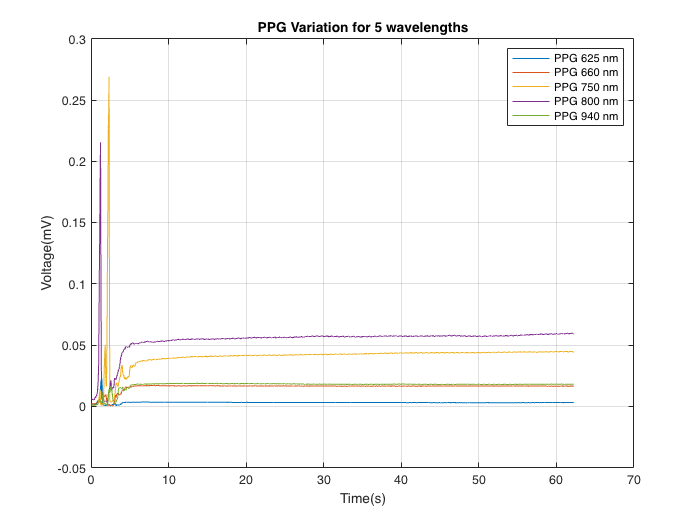

% Intensity Normalization

PPG_625_Norm = PPG_625_array(1:1246,2)/9.9;
PPG_660_Norm = PPG_660_array(1:1246,2)/10.66;
PPG_750_Norm = PPG_750_array(1:1246,2)/10.66;
PPG_800_Norm = PPG_800_array(1:1246,2)/9.50;
PPG_940_Norm = PPG_940_array(1:1246,2)/10.68;

% Ploting
figure();
plot(PPG_Time,PPG_625_Norm), title('Avarage smootting PPG 625')
grid on
hold on
plot(PPG_Time,PPG_660_Norm) 
plot(PPG_Time,PPG_750_Norm)
plot(PPG_Time,PPG_800_Norm) 
plot(PPG_Time,PPG_940_Norm) 
title('PPG Variation for 5 wavelengths')
legend('PPG 625 nm', 'PPG 660 nm', 'PPG 750 nm', 'PPG 800 nm', 'PPG 940 nm')
xlabel('Time(s)')
ylabel('Voltage(mV)')
hold off 

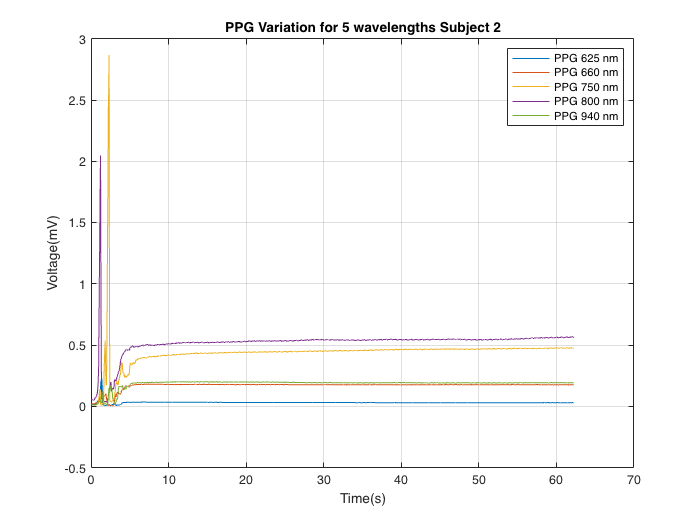

% Ploting
figure();
plot(PPG_Time,PPG_625), title('Avarage smootting PPG 625')
grid on
hold on
plot(PPG_Time,PPG_660) 
plot(PPG_Time,PPG_750)
plot(PPG_Time,PPG_800) 
plot(PPG_Time,PPG_940) 
title('PPG Variation for 5 wavelengths Subject 2')
legend('PPG 625 nm', 'PPG 660 nm', 'PPG 750 nm', 'PPG 800 nm', 'PPG 940 nm')
xlabel('Time(s)')
ylabel('Voltage(mV)')
hold off 

### Detrending Data

The above signal shows a baseline shift and therefore does not represent the true amplitude. In order to remove the trend, fit a low order polynomial to the signal and use the polynomial to detrend it.

numberPol = 50;
[p,s,mu] = polyfit((1:numel(PPG_625))',PPG_625,numberPol);

f_y_625 = polyval(p,(1:numel(PPG_625))',[],mu);
%f_y_625=f_y_625';
PPG_data_625 = PPG_625 - f_y_625;        % Detrend data 750

[p,s,mu] = polyfit((1:numel(PPG_660))',PPG_660,numberPol);

f_y_660 = polyval(p,(1:numel(PPG_660))',[],mu);
%f_y_660=f_y_660';
PPG_data_660 = PPG_660 - f_y_660;        % Detrend data 660

[p,s,mu] = polyfit((1:numel(PPG_750))',PPG_750,numberPol);

f_y_750 = polyval(p,(1:numel(PPG_750))',[],mu);
%f_y_750=f_y_750';
PPG_data_750 = PPG_750 - f_y_750;        % Detrend data 750

[p,s,mu] = polyfit((1:numel(PPG_800))',PPG_800,numberPol);

f_y_800 = polyval(p,(1:numel(PPG_800))',[],mu);
%f_y_800=f_y_800';
PPG_data_800 = PPG_800 - f_y_800;        % Detrend data 750

[p,s,mu] = polyfit((1:numel(PPG_940))',PPG_940,numberPol);

f_y_940 = polyval(p,(1:numel(PPG_940))',[],mu);
%f_y_940=f_y_940';
PPG_data_940 = PPG_940 - f_y_940;        % Detrend data 750


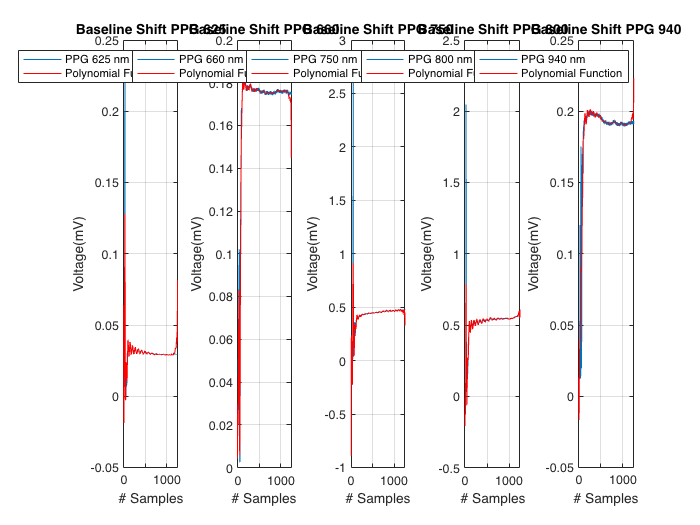

figure();
subplot(1,5,1)
plot(PPG_625)
title('Baseline Shift PPG 625')
grid on
hold on
plot(f_y_625,'r');
legend('PPG 625 nm', 'Polynomial Function')
xlabel('# Samples')
ylabel('Voltage(mV)')
hold off

subplot(1,5,2)
plot(PPG_660)
title('Baseline Shift PPG 660')
grid on
hold on
plot(f_y_660,'r');
legend('PPG 660 nm', 'Polynomial Function')
xlabel('# Samples')
ylabel('Voltage(mV)')

subplot(1,5,3)
plot(PPG_750)
title('Baseline Shift PPG 750')
grid on
hold on
plot(f_y_750,'r');
legend('PPG 750 nm', 'Polynomial Function')
xlabel('# Samples')
ylabel('Voltage(mV)')

subplot(1,5,4)
plot(PPG_800)
title('Baseline Shift PPG 800')
grid on
hold on
plot(f_y_800,'r');
legend('PPG 800 nm', 'Polynomial Function')
xlabel('# Samples')
ylabel('Voltage(mV)')
hold off

subplot(1,5,5)
plot(PPG_940)
title('Baseline Shift PPG 940')
grid on
hold on
plot(f_y_940,'r');
legend('PPG 940 nm', 'Polynomial Function')
xlabel('# Samples')
ylabel('Voltage(mV)')
hold off

### **Thresholding to Find Peaks of Interest**

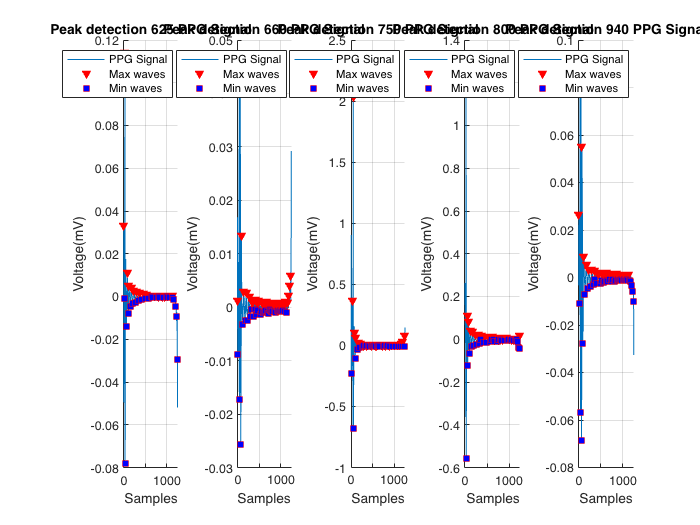

t = 1:length(PPG_data_625);

% Peaks for 625
[~,locs_Rwave_625] = findpeaks(PPG_data_625,'MinPeakHeight',0.0001,...
                                    'MinPeakDistance',20);
% Finding Local Minima in Signal
PPG_inverted_625 = -PPG_data_625;
[~,locs_Swave_625] = findpeaks(PPG_inverted_625,'MinPeakHeight',0.0001,...
                                        'MinPeakDistance',20);

% Peaks for 660
[~,locs_Rwave_660] = findpeaks(PPG_data_660,'MinPeakHeight',0.0004,...
                                    'MinPeakDistance',20);
% Finding Local Minima in Signal
PPG_inverted_660 = -PPG_data_660;
[~,locs_Swave_660] = findpeaks(PPG_inverted_660,'MinPeakHeight',0.0004,...
                                        'MinPeakDistance',20);

% Peaks for 750
[~,locs_Rwave_750] = findpeaks(PPG_data_750,'MinPeakHeight',0.0002,...
                                    'MinPeakDistance',20);
% Finding Local Minima in Signal
PPG_inverted_750 = -PPG_data_750;
[~,locs_Swave_750] = findpeaks(PPG_inverted_750,'MinPeakHeight',0.0002,...
                                        'MinPeakDistance',20);

% Peaks for 800
[~,locs_Rwave_800] = findpeaks(PPG_data_800,'MinPeakHeight',0.0002,...
                                    'MinPeakDistance',20);
% Finding Local Minima in Signal
PPG_inverted_800 = -PPG_data_800;
[~,locs_Swave_800] = findpeaks(PPG_inverted_800,'MinPeakHeight',0.0002,...
                                        'MinPeakDistance',20);

% Peaks for 940
[~,locs_Rwave_940] = findpeaks(PPG_data_940,'MinPeakHeight',0.0007,...
                                    'MinPeakDistance',20);
% Finding Local Minima in Signal
PPG_inverted_940 = -PPG_data_940;
[~,locs_Swave_940] = findpeaks(PPG_inverted_940,'MinPeakHeight',0.0007,...
                                        'MinPeakDistance',20);
figure

subplot(1,5,1)
hold on 
plot(t,PPG_data_625)
plot(locs_Rwave_625,PPG_data_625(locs_Rwave_625),'rv','MarkerFaceColor','r')
plot(locs_Swave_625,PPG_data_625(locs_Swave_625),'rs','MarkerFaceColor','b')
grid on
legend('PPG Signal','Max waves','Min waves')
xlabel('Samples')
ylabel('Voltage(mV)')
title('Peak detection 625 PPG Signal')
hold off

subplot(1,5,2)
hold on 
plot(t,PPG_data_660)
plot(locs_Rwave_660,PPG_data_660(locs_Rwave_660),'rv','MarkerFaceColor','r')
plot(locs_Swave_660,PPG_data_660(locs_Swave_660),'rs','MarkerFaceColor','b')
grid on
legend('PPG Signal','Max waves','Min waves')
xlabel('Samples')
ylabel('Voltage(mV)')
title('Peak detection 660 PPG Signal')

subplot(1,5,3)
hold on 
plot(t,PPG_data_750)
plot(locs_Rwave_750,PPG_data_750(locs_Rwave_750),'rv','MarkerFaceColor','r')
plot(locs_Swave_750,PPG_data_750(locs_Swave_750),'rs','MarkerFaceColor','b')
grid on
legend('PPG Signal','Max waves','Min waves')
xlabel('Samples')
ylabel('Voltage(mV)')
title('Peak detection 750 PPG Signal')
hold off

subplot(1,5,4)
hold on 
plot(t,PPG_data_800)
plot(locs_Rwave_800,PPG_data_800(locs_Rwave_800),'rv','MarkerFaceColor','r')
plot(locs_Swave_800,PPG_data_800(locs_Swave_800),'rs','MarkerFaceColor','b')
grid on
legend('PPG Signal','Max waves','Min waves')
xlabel('Samples')
ylabel('Voltage(mV)')
title('Peak detection 800 PPG Signal')
hold off

subplot(1,5,5)
hold on 
plot(t,PPG_data_940)
plot(locs_Rwave_940,PPG_data_940(locs_Rwave_940),'rv','MarkerFaceColor','r')
plot(locs_Swave_940,PPG_data_940(locs_Swave_940),'rs','MarkerFaceColor','b')
grid on
legend('PPG Signal','Max waves','Min waves')
xlabel('Samples')
ylabel('Voltage(mV)')
title('Peak detection 940 PPG Signal')
hold off

## Elimination negative values


DC_625 = min(PPG_data_625);
PPG_data_625 = PPG_data_625 + (-1)*DC_625;

DC_660 = min(PPG_data_660);
PPG_data_660 = PPG_data_660 + (-1)*DC_660;

DC_750 = min(PPG_data_750);
PPG_data_750 = PPG_data_750 + (-1)*DC_750;

DC_800 = min(PPG_data_800);
PPG_data_800 = PPG_data_800 + (-1)*DC_800;

DC_940 = min(PPG_data_940);
PPG_data_940 = PPG_data_940 + (-1)*DC_940;

### Beer Lambert Law


$$I=I_{0}e^{-\epsilon(\lambda)cd}$$


I_625   = mean(PPG_data_625 (locs_Rwave_625 ));
I_o_625  = mean(PPG_data_625 (locs_Swave_625 ));

I_660   = mean(PPG_data_660 (locs_Rwave_660 ));
I_o_660  = mean(PPG_data_660 (locs_Swave_660 ));

I_750   = mean(PPG_data_750(locs_Rwave_750));
I_o_750 = mean(PPG_data_750(locs_Swave_750));

I_800  = mean(PPG_data_800(locs_Rwave_800));
I_o_800 = mean(PPG_data_800(locs_Swave_800));

I_940   = mean(PPG_data_940(locs_Rwave_940));
I_o_940 = mean(PPG_data_940(locs_Swave_940));


The absorption Coefficient of this process is a measure of the rate of decrease in the intensity of the light as it passes through a given substance:


$$A=-ln(T)=-ln(\frac{I}{I_0})=\epsilon(\lambda)Cd$$


A_625 = (-1)*log(I_625/I_o_625);
A_660  = (-1)*log(I_660 /I_o_660);
A_750 = (-1)*log(I_750/I_o_750);
A_800 = (-1)*log(I_800/I_o_800);
A_940 = (-1)*log(I_940/I_o_940);

### Espectral Response

The data for the extinction coefficient:

load('ExtintionCoeff.mat');

Error using load
'ExtintionCoeff.mat' is not found in the current folder or on the MATLAB path, but exists in:
    /Volumes/GoogleDrive/My Drive/Investigacion/Research/Research Project NSF EPSCoR CAWT/Deep Learning

Change the MATLAB current folder or add its folder to the MATLAB path.

% Oxyhemoglobin
figure()
semilogy(Hemoglobin.Wave,Hemoglobin.Hbo2,'r-','linewidth',3);
axis([250 1000 100 1000000]);
set(gca,'FontSize', [18]);
grid on;
%title('Oxyhemoglobin','fontsize',18);
ylabel('molar extinction coefficient (cm^{-1} (moles/l)^{-1})','fontsize',18);
xlabel('wavelength (nm)','fontsize',18);

hold on;
% Deoxyhemoglobin
semilogy(Hemoglobin.Wave,Hemoglobin.Hb,'b-','linewidth',3);
axis([250 1000 100 1000000]);
set(gca,'FontSize', [18]);
grid on;
%title('Deoxyhemoglobin','fontsize',18);
ylabel('molar extinction coefficient (cm^{-1} (moles/l)^{-1})','fontsize',18);
xlabel('wavelength (nm)','fontsize',18);
legend('Oxyhemoglobin','Deoxyhemoglobin');
hold off;

eHb_625     = (Hemoglobin.Hb(188) + Hemoglobin.Hb(189))/2;
eO2Hb_625   = (Hemoglobin.Hbo2(188) + Hemoglobin.Hbo2(189))/2;

eHb_660     = Hemoglobin.Hb(206);
eO2Hb_660   = Hemoglobin.Hbo2(206);

eHb_750     = Hemoglobin.Hb(251);
eO2Hb_750   = Hemoglobin.Hbo2(251);

eHb_800     = Hemoglobin.Hb(276);
eO2Hb_800   = Hemoglobin.Hbo2(276);

eHb_940     = Hemoglobin.Hb(376);
eO2Hb_940   = Hemoglobin.Hbo2(376);


Total_extint = [eHb_660  eO2Hb_660; eHb_750  eO2Hb_750; eHb_800  eO2Hb_800; eHb_940  eO2Hb_940];

### Hemoglobin measurements

In the case of the hemoglobin concentration prediction, in the last section, we got that the absorption for a different substance was given by: 

Absortion_subject1 = [A_660 A_750 A_800 A_940];

% Saudo Inversa
Ex = pinv(Total_extint);
%molecularweight = 64500 ; 
Concentrations.subject1 = Ex*Absortion_subject1'

### Oxigen Saturation

If we use we use only functional Hemoglobin and two wavelengths as in the case of the pulse oximeter, then the absorption will be:


$$A_{\lambda_{1}}=\epsilon_{\lambda_{1}O_{2}Hb}C_{O_{2}Hb}d+\epsilon_{\lambda_{1}RHb}C_{RHb}d$$



$$A_{\lambda_{2}}=\epsilon_{\lambda_{2}O_{2}Hb}C_{O_{2}Hb}d+\epsilon_{\lambda_{2}RHb}C_{RHb}d$$


The ratio of the absorbance at two wavelengths:


$$R=\frac{A_{\lambda_{1}}}{A_{\lambda_{2}}}=\frac{\epsilon_{\lambda_{1}O_{2}Hb}C_{O_{2}Hb}d+\epsilon_{\lambda_{1}RHb}C_{RHb}d}{\epsilon_{\lambda_{2}O_{2}Hb}C_{O_{2}Hb}d+\epsilon_{\lambda_{2}RHb}C_{RHb}d}$$


% R = 2.0647/2.1358; % Data normalizada

% R = 0.0281/0.0360;  % Data no normalizada

R = A_625/A_750;

Assuming that the optical path length of the two-wavelength is equal to 'd' can be removed in the ratio. W can rewrite the equation as a function of the ratio to calculate de Oxygen saturation.


$$S_{a}O_{2}=\frac{\epsilon_{\lambda_{1}RHb}-\epsilon_{\lambda_{2}RHb}R}{\epsilon_{\lambda_{1}RHb}-\epsilon_{\lambda_{1}O_{2}Hb}+[\epsilon_{\lambda_{1}O_{2}Hb}-\epsilon_{\lambda_{1}RHb}]R}*100$$


R = A_625/A_750;
SaO2 = ((eHb_625-(eHb_660)*R)./(eHb_625-eO2Hb_625+(eO2Hb_660-eHb_660)*R))*100

% Ratio 625
R = A_625/A_660;
SaO2 = ((eHb_625-(eHb_660)*R)./(eHb_625-eO2Hb_625+(eO2Hb_660-eHb_660)*R))*100

R = A_625/A_750;
SaO2 = ((eHb_625-(eHb_750)*R)./(eHb_625-eO2Hb_625+(eO2Hb_750-eHb_750)*R))*100

R = A_625/A_800;
SaO2 = ((eHb_625-(eHb_800)*R)./(eHb_625-eO2Hb_625+(eO2Hb_800-eHb_800)*R))*100

R = A_625/A_940;
SaO2 = ((eHb_625-(eHb_940)*R)./(eHb_625-eO2Hb_625+(eO2Hb_940-eHb_940)*R))*100

% Ratio 660
R = A_660/A_625;
SaO2 = ((eHb_660-(eHb_625)*R)./(eHb_660-eO2Hb_660+(eO2Hb_625-eHb_625)*R))*100

R = A_660/A_750;
SaO2 = ((eHb_660-(eHb_750)*R)./(eHb_660-eO2Hb_660+(eO2Hb_750-eHb_750)*R))*100

R = A_660/A_800;
SaO2 = ((eHb_660-(eHb_800)*R)./(eHb_660-eO2Hb_660+(eO2Hb_800-eHb_800)*R))*100

R = A_660/A_940;
SaO2 = ((eHb_660-(eHb_940)*R)./(eHb_660-eO2Hb_660+(eO2Hb_940-eHb_940)*R))*100
% Ratio 750

R = A_750/A_625;
SaO2 = ((eHb_750-(eHb_625)*R)./(eHb_750-eO2Hb_750+(eO2Hb_625-eHb_625)*R))*100

R = A_750/A_660;
SaO2 = ((eHb_750-(eHb_660)*R)./(eHb_750-eO2Hb_750+(eO2Hb_660-eHb_660)*R))*100

R = A_750/A_800;
SaO2 = ((eHb_750-(eHb_800)*R)./(eHb_750-eO2Hb_750+(eO2Hb_800-eHb_800)*R))*100

R = A_750/A_940;
SaO2 = ((eHb_750-(eHb_940)*R)./(eHb_750-eO2Hb_750+(eO2Hb_940-eHb_940)*R))*100

% Ratio 800

R = A_800/A_625;
SaO2 = ((eHb_800-(eHb_625)*R)./(eHb_800-eO2Hb_800+(eO2Hb_625-eHb_625)*R))*100

R = A_800/A_660;
SaO2 = ((eHb_800-(eHb_660)*R)./(eHb_800-eO2Hb_800+(eO2Hb_660-eHb_660)*R))*100

R = A_800/A_750;
SaO2 = ((eHb_800-(eHb_750)*R)./(eHb_800-eO2Hb_800+(eO2Hb_750-eHb_750)*R))*100

R = A_800/A_940;
SaO2 = ((eHb_800-(eHb_940)*R)./(eHb_800-eO2Hb_800+(eO2Hb_940-eHb_940)*R))*100

% Ratio 940

R = A_940/A_625;
SaO2 = ((eHb_940-(eHb_625)*R)./(eHb_940-eO2Hb_940+(eO2Hb_625-eHb_625)*R))*100

R = A_940/A_660;
SaO2 = ((eHb_940-(eHb_660)*R)./(eHb_940-eO2Hb_940+(eO2Hb_660-eHb_660)*R))*100

R = A_940/A_750;
SaO2 = ((eHb_940-(eHb_750)*R)./(eHb_940-eO2Hb_940+(eO2Hb_750-eHb_750)*R))*100

R = A_940/A_800;
SaO2 = ((eHb_940-(eHb_800)*R)./(eHb_940-eO2Hb_940+(eO2Hb_800-eHb_800)*R))*100

% Calibration Curve for 3 test

%%----------Oxigen Saturation-----------%% 
oxigen_larry = 98;
oxigen_michael = 96;
oxigen_maria = 98;

The ratio of the absorbance at two wavelengths:


$$R=\frac{A_{\lambda_{1}}}{A_{\lambda_{2}}}=\frac{\epsilon_{\lambda_{1}O_{2}Hb}C_{O_{2}Hb}d+\epsilon_{\lambda_{1}RHb}C_{RHb}d}{\epsilon_{\lambda_{2}O_{2}Hb}C_{O_{2}Hb}d+\epsilon_{\lambda_{2}RHb}C_{RHb}d}$$


% Ratio larry
R_larry = A_larry(1,1)/A_larry(1,4);

% Ratio michael
R_michael = A_michael(1,1)/A_michael(1,4);

% Ratio maria
R_maria = A_maria(1,1)/A_maria(1,4);




%%----------Hemoglbin Values-----------%%

Hemoglobin_larry = 15.6;
Hemoglobin_michael = 13.2;
Hemoglobin_maria = 11.7;


Hb(1,1) = C.larry(1,1);
Hb(1,2) = C.michael(1,1);
Hb(1,3) = C.maria(1,1);
Hbo2(1,1) = C.larry(2,1);
Hbo2(1,2) = C.michael(2,1);
Hbo2(1,3) = C.maria(2,1);

samples = linspace(1,3,3);

